# MATLAB: ATRACTOR DE LORENZ

## 1. Pequeño ejemplo de la función lorenz

        x' = sigma(y - x)

        y' = Rx - y - x*z

        z' = x*y - b*z

% Valores caóticos
sigma = 10;
rho = 28;
beta = 8/3;

% Calculamos eta
eta = sqrt(beta*(rho-1));

% Puntos críticos
yc1 = [0, 0, 0];
yc2 = [eta, eta, rho-1];
yc3 = [-eta, -eta, rho-1];

% Span de tiempo
tspan = 0.001:0.001:60;

% Condición inicial
y0 = [0.001, 0.001, 0.001];

% Atractor de Lorenz
[t,y] = ode45(@(t,y)F_lorenz(t, y, [sigma, rho, beta]), tspan, y0)

t =     0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090
    0.0100


y =     0.0010    0.0010    0.0010
    0.0010    0.0010    0.0010
    0.0010    0.0011    0.0010
    0.0010    0.0011    0.0010
    0.0010    0.0011    0.0010
    0.0010    0.0011    0.0010
    0.0010    0.0012    0.0010
    0.0010    0.0012    0.0010
    0.0010    0.0012    0.0010
    0.0010    0.0012    0.0010


## 2. Gráfica atractor de Lorenz

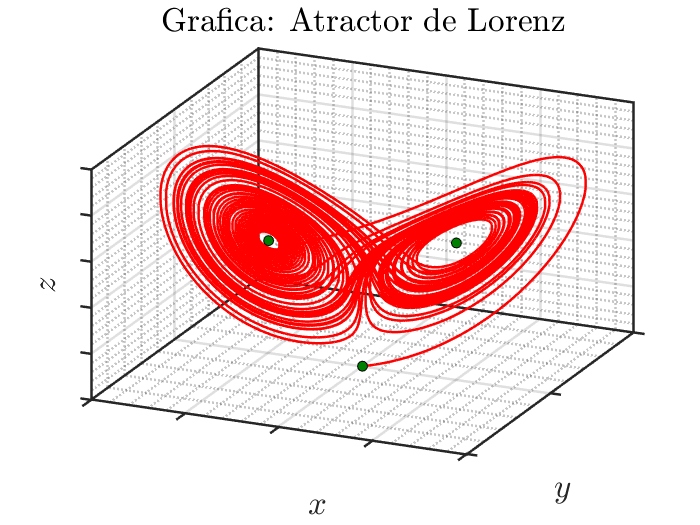

% Gráfica
plot3(y(:,1), y(:,2), y(:,3), 'b-', 'LineWidth', 1.5, 'Color', 'red');
hold on;

% Puntos Críticos
plot3(yc1(1),yc1(2),yc1(3),'o','MarkerFaceColor', '[0, 0.5, 0]', 'MarkerEdgeColor','black');
plot3(yc2(1),yc2(2),yc2(3),'o','MarkerFaceColor', '[0, 0.5, 0]', 'MarkerEdgeColor','black');
plot3(yc3(1),yc3(2),yc3(3),'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black')
hold off;

% Límites gráfica
xlim([-20, 20]); ylim([-50, 50]); zlim([0, 50]);

% Estílo de la gráfica
grid on; box on; grid minor;
xticklabels({});yticklabels({});zticklabels({});
title ('Grafica: Atractor de Lorenz','Interpreter','latex'); 
xlabel('$x$','Interpreter','latex','FontSize',26,'FontWeight','bold');
ylabel('$y$','Interpreter','latex','FontSize',26,'FontWeight','bold');
zlabel('$z$','Interpreter','latex','FontSize',26,'FontWeight','bold');
set(gca,'FontSize',18,'LineWidth',1.5);
view(180*8000/length(tspan),30)

## 3. Animación atractor de Lorenz

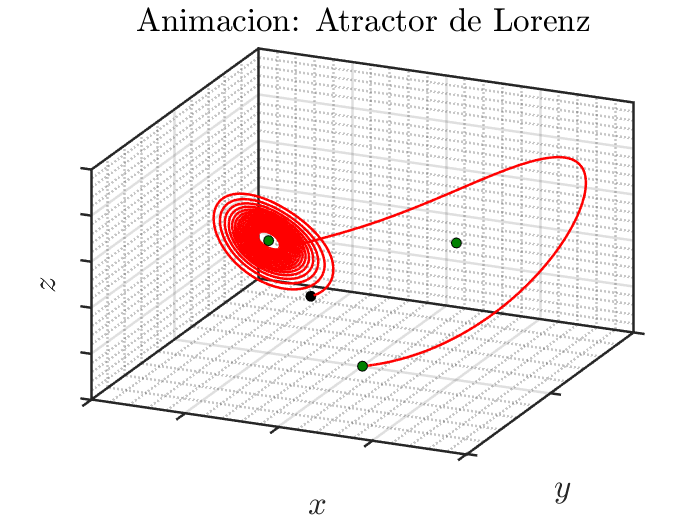

% Video

% Iterador de Frames
for i =1:50:length(tspan)
    pause(0.001)
    % Atractor de Lorenz
    plot3(y(1:i,1),y(1:i,2),y(1:i,3),'b-', 'LineWidth', 1.5, 'Color', 'red');
    hold on;
    
    % Graficar puntos críticos
    plot3(yc1(1),yc1(2),yc1(3),'o','MarkerFaceColor', '[0, 0.5, 0]', 'MarkerEdgeColor','black');
    plot3(yc2(1),yc2(2),yc2(3),'o','MarkerFaceColor', '[0, 0.5, 0]', 'MarkerEdgeColor','black');
    plot3(yc3(1),yc3(2),yc3(3),'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
    
    % Graficar punto actual
    plot3(y(i,1),y(i,2),y(i,3),'ko','MarkerFaceColor', 'black', 'MarkerEdgeColor', 'black')
    hold off;
    
    % Límites gráfica
    xlim([-20, 20]); ylim([-50, 50]); zlim([0, 50]);
    
    % Estilo de la gráfica
    grid on; box on; grid minor;
    xticklabels({});yticklabels({});zticklabels({});
    title ('Animacion: Atractor de Lorenz','Interpreter','latex'); 
    xlabel('$x$','Interpreter','latex','FontSize',26,'FontWeight','bold');
    ylabel('$y$','Interpreter','latex','FontSize',26,'FontWeight','bold');
    zlabel('$z$','Interpreter','latex','FontSize',26,'FontWeight','bold');
    set(gca,'FontSize',18,'LineWidth',1.5);
    view(180*8000/length(tspan),30)
end